%Boaz Porat.

#### Actividad 1 

#### Tipos de Filtros IIR

**Se requiere diseñar un filtro discreto IIR, pasa bajos, tipo Butterworth, con 𝛿 p=0.2, 𝛿s=0.1, 𝜔p = 0.32𝜋 , 𝜔s = 0.6𝜋. **

**1) Encuentre las especificaciones para el dominio continuo (𝛺). **

**2) Encuentre el orden N y la frecuencia de corte 𝛺 c que cumple con las especificaciones. **

**3) Encuentre los polos del filtro H(s) y grafique el diagrama de polos y ceros en el plano s. **

**4) Encuentre la transferencia H(z) en el dominio discreto con sus polos, ceros y el factor de escalamiento. Grafique los polos y ceros en el plano z. **

**5) Determine los coeficientes a y b de H(z) y grafique la respuesta en frecuencia de tiempo discreto |H(𝜔)|. Verifique el cumplimiento de las especificaciones. Ayuda: coef = poly(raices) **

%- Especificaciones en tiempo discreto
clc; clear; close all;
deltaP = 0.2;
deltaS = 0.1;
wp = 0.32*pi;
ws = 0.6*pi;
%Para usar el Butterworth necesito el  Wc y el N.

%- Tranformacion a tiempo continuo:
T = 2; % puede ser cualquiera, total vamos a transformar de continuo a discreto y volver.
OmegaP = 2*tan(wp/2)/T; %rad/s
OmegaS = 2*tan(ws/2)/T; %rad/s

%orden del filtro:
%N = 0.5 * ( log( 1/(deltas^2) -1 ) / log(OmegaS/OmegaP))
%Yo tengo este caso.
%N >= log( sqrt( ((1-deltaP)^(-2) - 1) / (OmegaP/OmegaS) ) )

%- Diseño del filtro analogico H(S):
N = log( sqrt( ( (1 - deltaP)^(-2) - 1 ) / (deltaS^(-2) - 1) ) ) / ...
        log(OmegaP/OmegaS);
N= ceil(N)

N = 3

%N=3
OmegaC = 0.5 * ( OmegaP/( (1-deltaP)^(-2) - 1 )^( 1/(2*N) ) + ...
                OmegaS/( (deltaS)^(-2) - 1 )^( 1/(2*N) ) )

OmegaC = 0.6225

%OmegaC = 0.62 rad/s
%-3
Hw =@(Omega, OmegaC, N)( 1/( 1 + (Omega/OmegaC)^(2*N) )  ); 

%[b , a] = butter(N, OmegaC)
%freqz(b, a, [], 1/T)

%Tranformacion bilineal(s,z).
Ts= @(Z,T)( (2/T)*(Z-1)/(Z+1) );
Tz= @(S,T)((1 + T*S/2)/(1 - T*S/2));
%
%nfft = 8192;
%[H, w] = freqz(b, a, nfft);
%zplane(b, a)

%a_ = Tz(a, T)
%b_ = Tz(b, T)
%A= prod(a_)

%Escalamiento
%A= 0.074;


# Algunos ejemplos IIR con MATLAB

**Utilizar las funciones de Matlab para obtener los coeficientes de un filtro discreto IIR tipo Butterworth con 𝜔 c = 0.35𝜋 y N=4, graficar: **

**1) La respuesta en frecuencia |H(𝜔)| **

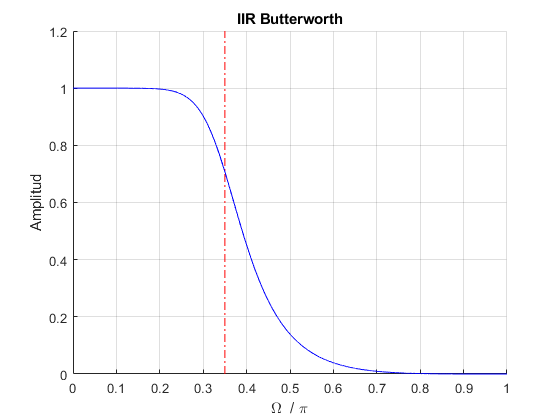

clc; clear; close all
wc = 0.35;
N = 4;
nfft = 8192;
%Butter
[b,a] = butter(N,wc);
[Hbutter,w] = freqz(b, a, nfft); % w frecuencia angular [rad] (0-2pi)
                           % H respuesta en frecuencia
                           % nfft cantidad de puntos de w
figure()
hold on
plot([wc wc],[0 1.2],'-.r')
plot(w/pi, abs(Hbutter), 'b');
grid on
ylabel("Amplitud")
xlabel("\Omega  / \pi")
title("IIR Butterworth")

**2) Los polos y ceros en el plano ‘z’ **

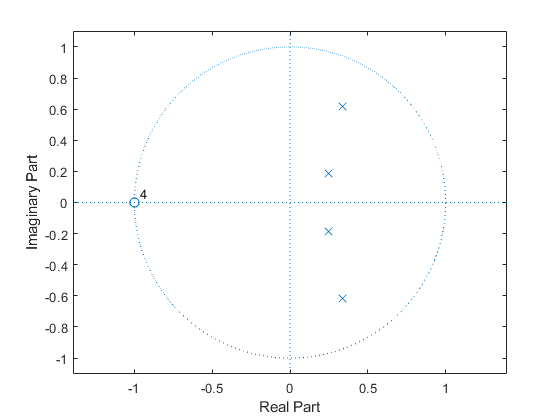

figure()
zplane(b, a)

**3) La respuesta en fase 𝛷(𝜔) **

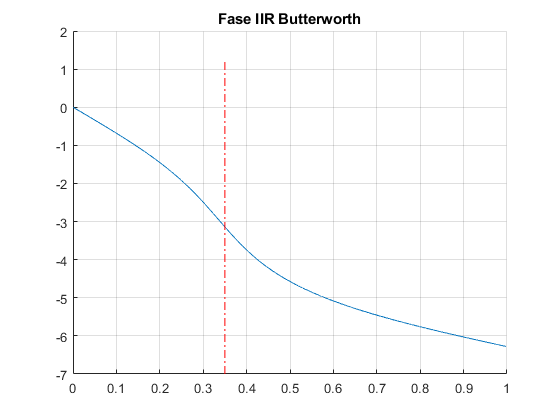

[A, w, phi] = zerophase(b, a, w);
figure()
hold on
plot(w/pi, phi)
plot([wc wc],[-7 1.2],'-.r')
title("Fase IIR Butterworth")
grid on

**4) Retardo de grupo**

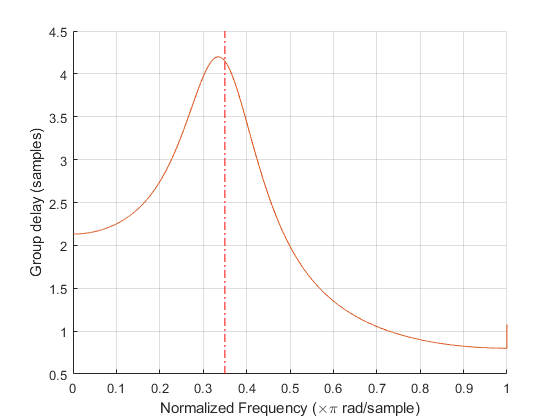

figure()
hold on
plot([wc wc],[0.5 4.5],'-.r')
grpdelay(b, a, nfft)

**Utilizar las funciones de Matlab para obtener los coeficientes de un filtro IIR tipo Chebyshev-I, con 𝛿p=0.1, 𝜔 p = 0.4𝜋 y N=4, graficar: **

**1) La respuesta en frecuencia |H(𝜔)| **

clc; clear; close all
wp = 0.4;
deltaP = 0.1;
Rp = -20*log10(1 - deltaP);
N = 4;

nfft = 8192;
%Butter
[b,a] = cheby1(N, Rp, wp)

b =     0.0250    0.1001    0.1501    0.1001    0.0250


a =     1.0000   -1.5704    1.7088   -0.9898    0.2960


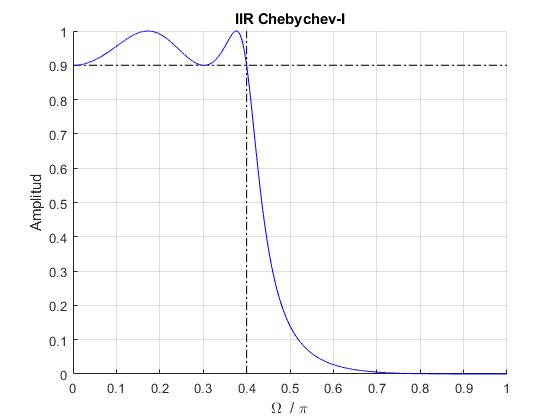

[Hcheby,w] = freqz(b, a, nfft); % w frecuencia angular [rad] (0-2pi)
                           % H respuesta en frecuencia
                           % nfft cantidad de puntos de w
figure()
hold on
plot([wp wp],[0 1],'-.k')
plot([0 1],[0.9 0.9],'-.k')
plot(w/pi, abs(Hcheby), 'b');
grid on
ylabel("Amplitud")
xlabel("\Omega  / \pi")
title("IIR Chebychev-I")

**2) La respuesta en fase 𝛷(𝜔) **

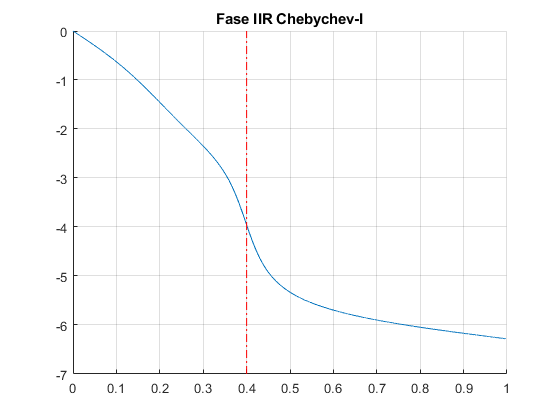

[A, w, phi] = zerophase(b, a, w);
figure()
hold on
plot(w/pi, phi)
plot([wp wp],[-7 0],'-.r')
title("Fase IIR Chebychev-I")
grid on

**3) Los polos y ceros en el plano ‘z’ **

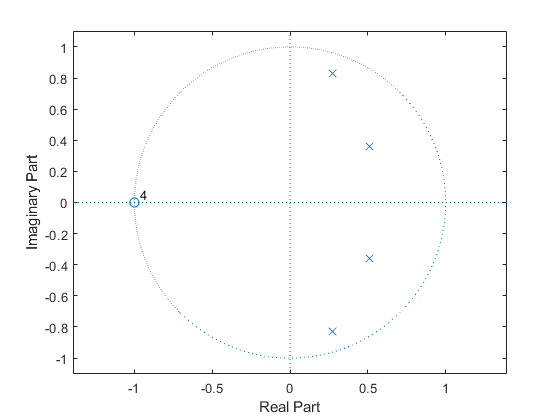

figure()
zplane(b, a)

**4) Retardo de grupo**

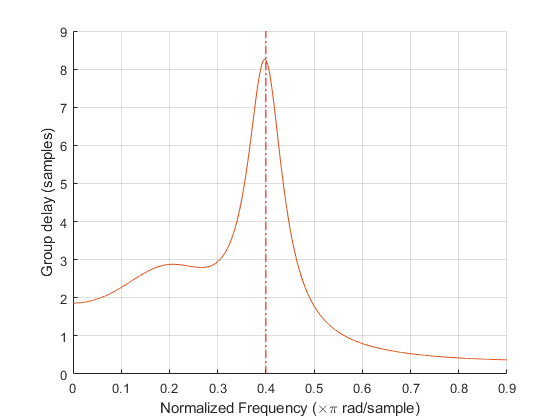

figure()
hold on
plot([wp wp],[0 9],'-.r')
grpdelay(b, a, nfft)
xlim([0 0.9])

y asi con todos los filtros

[https://campusgrado.fi.uba.ar/pluginfile.php/148781/mod_resource/content/3/practica%203%20%282c2022%29.pdf](https://campusgrado.fi.uba.ar/pluginfile.php/148781/mod_resource/content/3/practica%203%20%282c2022%29.pdf)